Testing file: task2_1.mat


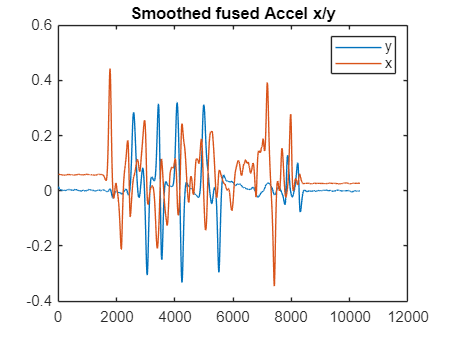

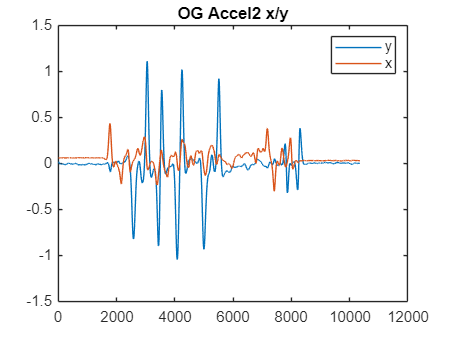

gyro_z =     0.0012
    0.0012
    0.0012
    0.0012
    0.0011
    0.0011
    0.0011
    0.0010
    0.0010
    0.0010


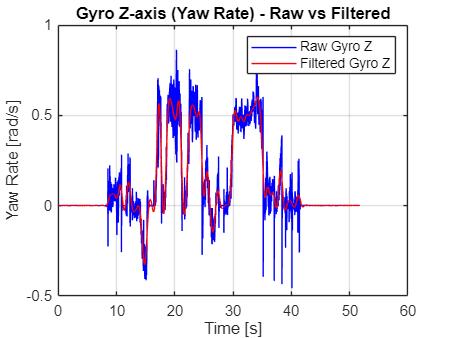

    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    0.0100

Step 50:z_pred:    1.1819
    1.9017
    1.2271

z_meas:    1.1640
    1.8840
    1.2090

Printing K:   -0.4982    0.0000    0.4981
    0.4916   -0.9959    0.4916
   -0.1197    0.0000    0.1197
    0.1188   -0.2393    0.1188
   -0.0242    0.0014   -0.0242

Step 100:z_pred:    1.1811
    1.8880
    1.2213

z_meas:    1.1630
    1.8700
    1.2030

Printing K:   -0.4995   -0.0000    0.4995
    0.4965   -0.9991    0.4965
   -0.2287    0.0000    0.2287
    0.2281   -0.4574    0.2281
   -0.0219   -0.0008   -0.0219

Step 150:z_pred:    1.1845
    1.9187
    1.2158

z_meas:    1.1660
    1.9000
    1.1970

Printing K:   -0.5000   -0.0000    0.4999
    0.4995   -1.0000    0.4995
   -0.3156    0.0000    0.3156
    0.3156   -0.6312    0.3156
   

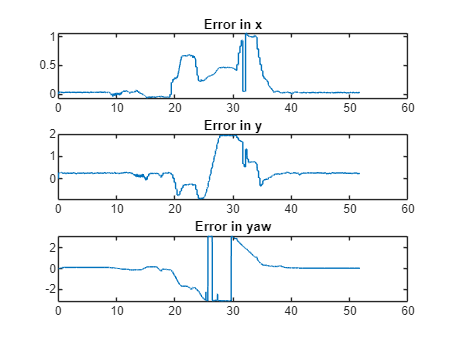

Absolute RMSE for task2_1.mat: 0.6153 m


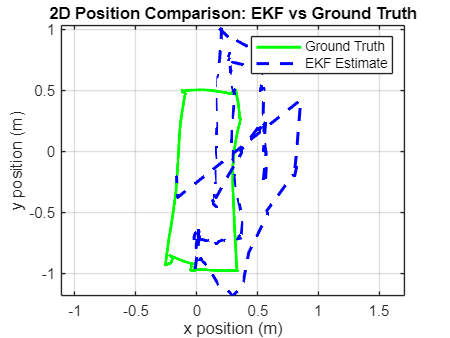

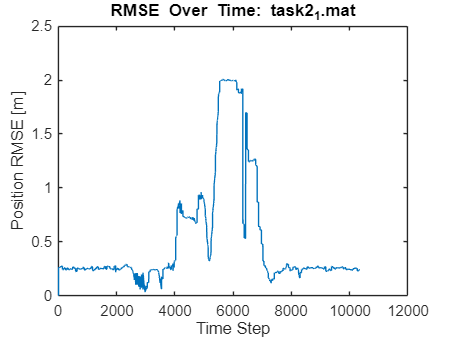

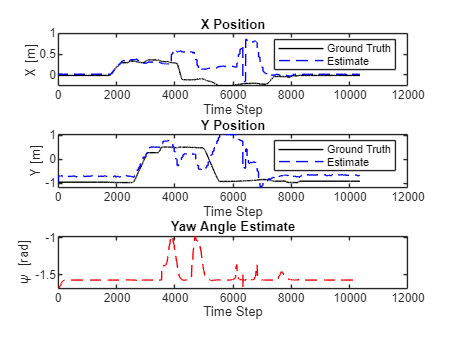

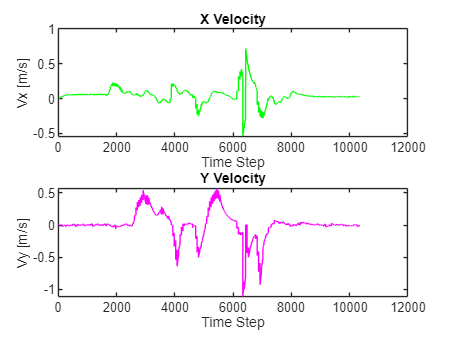

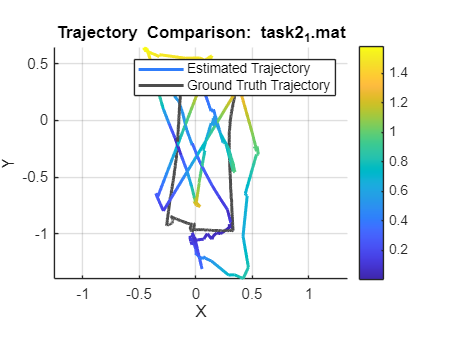

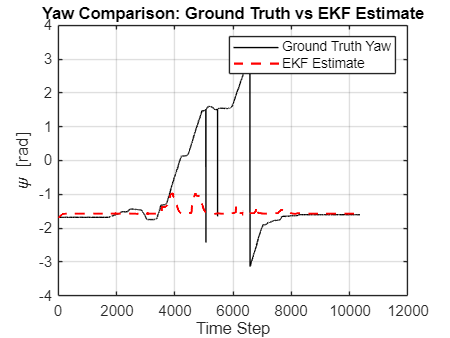

clear;clc; %Eval Script
taskFiles = { %'calib2_straight.mat'
    'task2_1.mat'%, 'task1_2.mat', 'task1_3.mat', 'task1_4.mat', ...
    %'task2_1.mat', 'task2_2.mat', 'task2_3.mat', 'task2_4.mat'
};

sensor_calibration_data = load('sensor_calibration.mat');


for k = 1:length(taskFiles)
    fprintf('\n==============================\n');
    fprintf('Testing file: %s\n', taskFiles{k});
    fprintf('==============================\n');

    try
        % Load the task file
        load(taskFiles{k}, 'out');


        % Call your EKF implementation
        warning('off', 'MATLAB:nearlySingularMatrix');  % disables that specific warning
        warning('on', 'all');                          % disables ALL warnings (if needed)


        [X_Est, P_Est, GT, gyro_z] = myEKF_nomag(out,diag([1, 1, 1.0, 1.0, 0.01]),diag([1,1,1]),1);



        % Convert ground truth to rigidtform3d
        pos = GT(:,1:3);
        N = size(pos,1);
        gtTforms(N) = rigidtform3d;
        for i = 1:N
            tGT = pos(i,:);
            RGT = eye(3);
            gtTforms(i) = rigidtform3d(RGT, tGT);
        end

        % Convert estimated states to rigidtform3d
        estTforms(N) = rigidtform3d;
        for i = 1:N
            tEst = [X_Est(i,1), X_Est(i,2), 0];
            R = eye(3);
            estTforms(i) = rigidtform3d(R, tEst);
        end

        % Compare trajectories
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');
        fprintf('Absolute RMSE for %s: %.4f m\n', taskFiles{k}, metrics.AbsoluteRMSE(2));
        % Extract x and y from the state estimate and ground truth
        x_est = X_Est(:,1);
        y_est = X_Est(:,2);
 
        x_gt = GT(:,1);
        y_gt = GT(:,2);
        
        % Plotting
        figure;
        plot(x_gt, y_gt, 'g-', 'LineWidth', 2); hold on;
        plot(x_est, y_est, 'b--', 'LineWidth', 2);
        legend('Ground Truth', 'EKF Estimate');
        xlabel('x position (m)');
        ylabel('y position (m)');
        title('2D Position Comparison: EKF vs Ground Truth');
        axis equal;
        grid on;


        % RMSE over time
        positionErrors = sqrt(sum((X_Est(:,1:2) - GT(:,1:2)).^2, 2));
        figure;
        plot(1:N, positionErrors);
        title(['RMSE Over Time: ', taskFiles{k}]);
        xlabel('Time Step'); ylabel('Position RMSE [m]');

        % Visualisation of all states
        figure;
        subplot(3,1,1);
        plot(1:N, GT(:,1), 'k-', 1:N, X_Est(:,1), 'b--');
        title('X Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('X [m]');

        subplot(3,1,2);
        plot(1:N, GT(:,2), 'k-', 1:N, X_Est(:,2), 'b--');
        title('Y Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('Y [m]');

        subplot(3,1,3);
        plot(1:N, X_Est(:,5), 'r--');
        title('Yaw Angle Estimate'); xlabel('Time Step'); ylabel('\psi [rad]');

        % Velocity visualisation
        figure;
        subplot(2,1,1);
        plot(1:N, X_Est(:,3), 'g'); title('X Velocity'); xlabel('Time Step'); ylabel('Vx [m/s]');
        subplot(2,1,2);
        plot(1:N, X_Est(:,4), 'm'); title('Y Velocity'); xlabel('Time Step'); ylabel('Vy [m/s]');


        figure;
        plot(metrics, 'absolute-translation');
        title(['Trajectory Comparison: ', taskFiles{k}]);
        view(0,90)
        rotate3d on;

        figure;
        plot(1:N,(GT(:,4)), 'k-')
        hold on
        plot(1:N, (X_Est(:,5)), 'r--', 'LineWidth', 1.5);
        hold off
        legend('Ground Truth Yaw', 'EKF Estimate');
        xlabel('Time Step');
        ylabel('\psi [rad]');
        title('Yaw Comparison: Ground Truth vs EKF Estimate');
        grid on;

     




    catch ME
        warning('Failed to process %s: %s', taskFiles{k}, ME.message);
    end
end